% preparing the test data
% loading the detector and the ground truth for the test images
load model/trained_yolov4_detector.mat detector
load labeled_data/parkingTrainGTFINISHED.mat gTruth

% creating a combined datastore of the images and bounding box data
[imds, blds] = objectDetectorTrainingData(gTruth);
testData = combine(imds, blds);

% running the data on test images
testResults = detect(detector, testData, "Threshold", 0.05)

testResults = 400×3 table
                    Boxes                        Scores            Labels      
    ______________________________________    ____________    _________________

    {[191.9529 105.8462 96.6884 104.9145]}    {[  0.8711]}    {[EV           ]}
    {[ 211.8806 128.9898 58.8174 60.5259]}    {[  0.8973]}    {[Accessible   ]}
    {[ 203.1673 128.0640 71.3490 59.2742]}    {[  0.9639]}    {[Accessible   ]}
    {[ 215.2876 141.6007 44.5311 41.2796]}    {[  0.9581]}    {[Accessible   ]}
    {[185.6389 94.3865 106.2091 139.3540]}    {[  0.9405]}    {[EV           ]}
    {2×4 single                          }    {2×1 single}    {2×1 categorical}
    {[123.0187 64.0892 145.7437 178.9573]}    {[  0.8994]}    {[EV           ]}
    {2×4 single                          }    {2×1 single}    {2×1 categorical}
    {[ 199.4727 94.1843 87.7657 130.1211]}    {[  0.7226]}    {[EV     

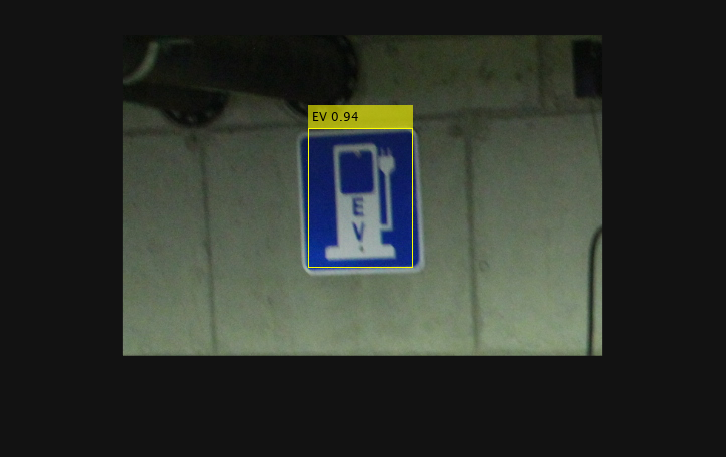

% visualizing detections
numImages = height(testResults);  % to set a limit on the control
imgIdx = 5;
img = readimage(imds, imgIdx);
label = string(testResults.Labels{imgIdx}) + " " + round(testResults.Scores{imgIdx},2);
img = insertObjectAnnotation(img, "rectangle", testResults.Boxes{imgIdx}, label);
imshow(img)

% evaluating detection results
% setting the IoU threshold. The default value is 0.5
iou = [0.5 0.25];

% evaluating the detector
metrics = evaluateObjectDetection(testResults, testData, iou);

% getting the class names to use later
classNames = metrics.ClassNames;

[datasetSummary, classSummary] = summarize(metrics)

datasetSummary = 1×4 table
    NumObjects    mAPOverlapAvg    mAP0.5     mAP0.25
    __________    _____________    _______    _______

       496           0.79049       0.73962    0.84137


classSummary = 3×4 table
                  NumObjects    APOverlapAvg     AP0.5     AP0.25 
                  __________    ____________    _______    _______

    Accessible       167          0.71916       0.67561     0.7627
    Charger          106          0.74751       0.67661    0.81841
    EV               223          0.90482       0.86664    0.94299


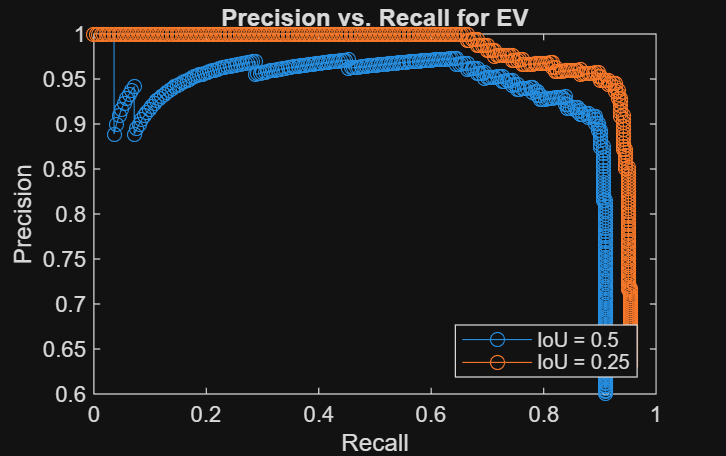

% visualizing precision-recall curves for different classes
[precision, recall, scores] = precisionRecall(metrics);

class = categorical({'EV', 'Charger', 'Accessible'});
class = class(1); % setting default selection to first option (EV)

% plotting precision-recall for IoU 1
plot(recall{class,1}, precision{class,1}, "-o")
xlim([0 1])
xlabel("Recall")
ylabel("Precision")
title("Precision vs. Recall for " + classNames(class))
hold on
% plotting precision-recall for IoU 2
plot(recall{class,2}, precision{class,2}, "-o")
hold off
legend(["IoU = " + iou(1); "IoU = " + iou(2)], "Location", "southeast")

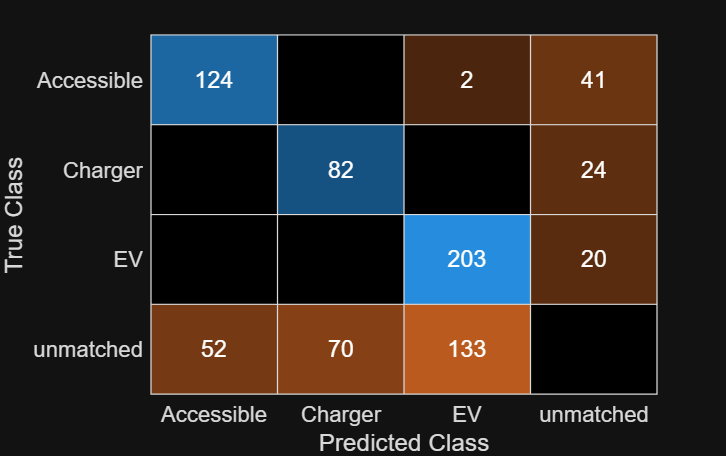

% visualizing the confusion matrix
[cm, confusionClasses] = confusionMatrix(metrics);
confusionchart(cm{1}, confusionClasses)

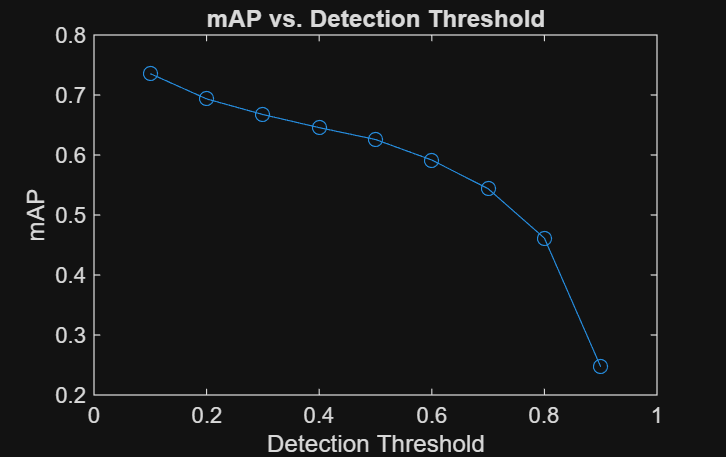

% choosing the best detection threshold
% vector of detection threshold values to test
thresholds = 0.1:0.1:0.9;

% createing a vector to store the results
mAPs = zeros(length(thresholds),1);

% creating a waitbar to monitor progress
f = waitbar(0);

% looping through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    currentMetrics = evaluateObjectDetection(results, testData, iou);
    datasetSummary = summarize(currentMetrics);
    mAPs(ii) = datasetSummary{:, "mAP0.5"};
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% visualizing the mAP vs detection threshold curve
plot(thresholds, mAPs, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")